# Demonstrates the parent-children relationship among graphic objects

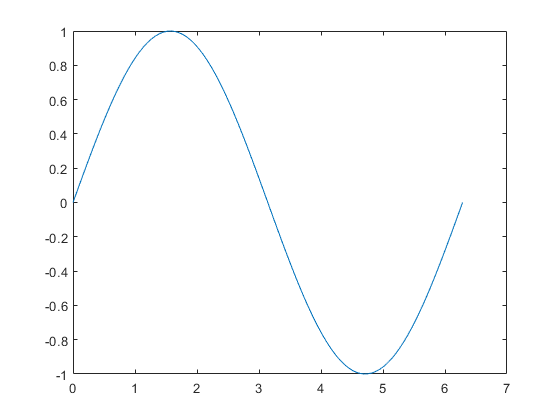

x = linspace(0,2*pi);
y = sin(x);
hCurve = plot(x,y);

hCurve.Parent % .Parent顯示plot的info

ans =   Axes with properties:

             XLim: [0 7]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


hAxes = hCurve.Parent;
hAxes.Parent

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


hFigure = hAxes.Parent;
hFigure.Parent

ans =   Graphics Root with properties:

          CurrentFigure: [1×1 Figure]
    ScreenPixelsPerInch: 96
             ScreenSize: [1 1 1920 1080]
       MonitorPositions: [2×4 double]
                  Units: 'pixels'

  Show all properties


hRoot = hFigure.Parent;
hRoot.Parent


ans = 

  0×0 empty GraphicsPlaceholder array.



hRoot.Children

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


hFigure.Children

ans =   Axes with properties:

             XLim: [0 7]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


hAxes.Children

ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


hCurve.Children


ans = 

  0×0 empty GraphicsPlaceholder array.



% delete(hCurve) % delete : 刪除繪圖物件
% delete(hAxes)
% delete(hFigure)

# Demonstrates the parent-children relationship among graphic objects.

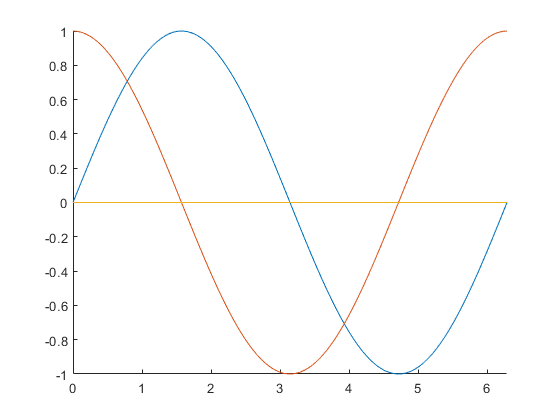

x = linspace(0,2*pi);
figure
axes('XLim', [0,2*pi], 'YLim', [-1,1])
hold on
plot(x, sin(x), x, cos(x))
plot([0,2*pi],[0,0])

hAxes = gca; % gca : 取得目前圖軸的編號
hCurve = hAxes.Children % 取得圖軸axes底下三個子物件

hCurve =   3×1 Line array:

  Line
  Line
  Line


% delete(hCurve(1))
% delete(hCurve(2))
% delete(hAxes)
% delete(gcf)

# Demonstrates the getting/setting of object properties.

x = linspace(0,2*pi);
hCurve = plot(x, sin(x));
get(hCurve, 'LineWidth') % 取得hCurve的LineWidth屬性

ans = 0.5000

% set(hCurve, 'LineWidth', 2) % LineWidth屬性設為2
hCurve.LineWidth = 2 % LineWidth屬性設為2(同上)

hCurve =   Line with properties:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


inspect(hCurve) % inspect開啟屬性檢查器
propedit % propedit開啟屬性編輯器
get(hCurve)
get(gcf)
get(gca)

# Demonstrates some properties of Figure objects.

scrsz = get(groot, 'ScreenSize');
h1 = figure;
    h1.Position = [20, 60, scrsz(3)/5, scrsz(4)/4];
    h1.Name = 'Bottom-left Figure Window';
h2 = figure;
    h2.Visible = 'off';
    h2.Units = 'normalized';
    h2.Position = [0.1, 0.2, 0.3, 0.4];
    h2.Visible = 'on';
    h2.Color = [0.8, 0.8, 0.8];
    h2.Name = 'A Window of Gray Background';
    h2.NumberTitle = 'off';
    h2.ToolBar = 'none';
    h2.MenuBar = 'none';
% delete(h1)
% delete(h2)

# Demonstrates some properties of Axes objects

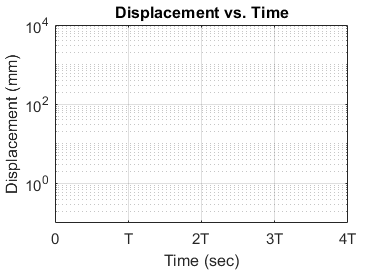

h = axes;
    xlabel('Time (sec)');
    ylabel('Displacement (mm)');
    title('Displacement vs. Time');
    axis([0, 20, 0, 10000]);
    grid on
    h.Box = 'on';
    h.YScale = 'log'; % 以log為刻度
    h.XTick = [0, 5, 10, 15, 20];
    h.XTickLabel = {'0', 'T', '2T', '3T', '4T'}; %修改刻度Label
    h.FontSize = 11;

% delete(h)
% delete(gcf)

# Demonstrates multiple Axes in a Figure. (pratice)

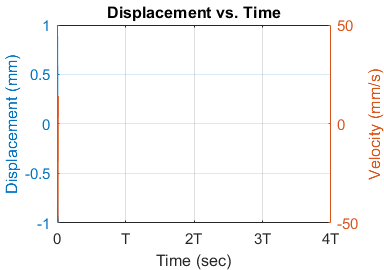

t = linspace(0,0.1); w = 50;
y = sin(w*t);
v = w*cos(w*t);
yyaxis left % 創建帶有y軸的圖表yyaxis left
hLine1 = plot(t, y);
xlabel('Time (sec)')
ylabel('Displacement (mm)')
yyaxis right % 創建帶有y軸的圖表yyaxis right
hLine2 = plot(t, v);
ylabel('Velocity (mm/s)')

% delete(hLine2)
% delete(hLine1)
% delete(gca)
% delete(gcf)

# Demonstrates the scaling of Axes.

t = linspace(0,2*pi);
plot(cos(t), sin(t))
axis equal

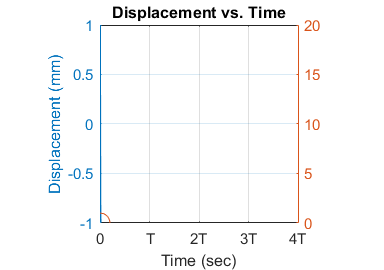

limits = axis;
axis square
axis([limits(1),limits(2),limits(1), limits(2)])

% delete(gca)
% delete(gcf)

# Demonstrates multiple plots (subplots) in a Figure (pratice sin,cos,tan, sinh.cosh,tanh)

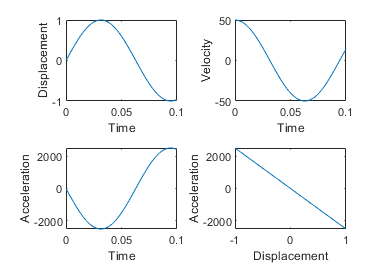

t = linspace(0,0.1); w = 50;
y = sin(w*t);
v = w*cos(w*t);
a = -w*w*sin(w*t);
h1 = subplot(2,2,1);
plot(t,y), xlabel('Time'), ylabel('Displacement')
h2 = subplot(2,2,2);
plot(t,v), xlabel('Time'), ylabel('Velocity')
h3 = subplot(2,2,3);
plot(t,a), xlabel('Time'), ylabel('Acceleration')
h4 = subplot(2,2,4);
plot(y,a), xlabel('Displacement'), ylabel('Acceleration')

% delete(h1)
% delete(h2)
% delete(h3)
% delete(h4)
% delete(gcf)

# Demonstrates the use of line styles, colors, and marker types. (pratice 多項式回歸)

x1 = [-5 -4 -3 -2 -1 0 1 2 3 4 5];
y1 = [23.9, 18.5, 10.7, 4.31, -0.26, -0.87, 0.82, 4.79, 7.67, 13.7, 23.5];
p = polyfit(x1, y1, 2) 

p =     0.9731   -0.2568   -0.0252


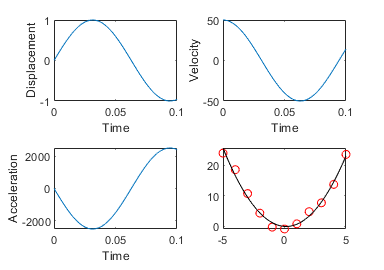

% polyfit : 以多項式函數尋找配合Ｘ資料之曲線 其中Ｘ為觀測值，n為模擬之階數。輸出參數p則為多項式之係數，S為特性矩陣
x2 = linspace(-5,5);
y2 = polyval(p, x2);
% polyval函數以產生預測值
h = plot(x1, y1, 'or', x2, y2, '-k');

% delete(h(1))
% delete(h(2))
% delete(gca)
% delete(gcf)

# Demonstrates additional line properties. (update 5*y) pratice

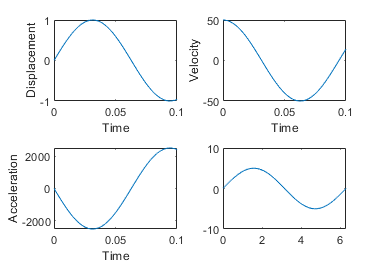

x = linspace(0,2*pi);
y = sin(x);
h = plot(x, y);
axis([0, 2*pi, -10, 10])
h.YData = 5*y;

% h.YData = 10*sin(x);

# Demonstrates some Text properties.

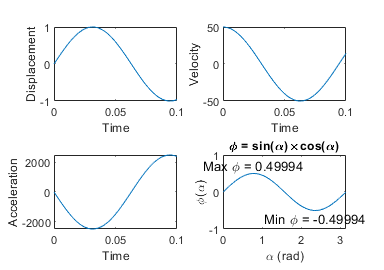

alpha = linspace(0, pi);
phi = sin(alpha).*cos(alpha);
plot(alpha, phi)
axis([0, pi, -1, 1])
hx = xlabel('\alpha (rad)');
hy = ylabel('\phi(\alpha)');
ht = title('\phi = sin(\alpha)\timescos(\alpha)');
    hx.FontSize = 16;
    hy.FontSize = 16;
    ht.FontSize = 18;
[value, index] = max(phi); % 找到phi的最高點value和index
hmax = text(alpha(index), value, ['Max \phi = ', num2str(value)]);
    hmax.HorizontalAlignment = 'center';
    hmax.VerticalAlignment = 'bottom';
[value, index] = min(phi); % 找到phi的最低點value和index
hmin = text(alpha(index), value, ['Min \phi = ', num2str(value)]);
    hmin.HorizontalAlignment = 'center';
    hmin.VerticalAlignment = 'top';

% delete(hx)
% delete(hy)
% delete(ht)
% delete(hmax)
% delete(hmin)
% delete(gcf)

# Demonstrates more Text properties.

x1 = [-5 -4 -3 -2 -1 0 1 2 3 4 5];
y1 = [23.9, 18.5, 10.7, 4.31, -0.26, -0.87, 0.82, 4.79, 7.67, 13.7, 23.5];
p = polyfit(x1, y1, 2)

p =     0.9731   -0.2568   -0.0252


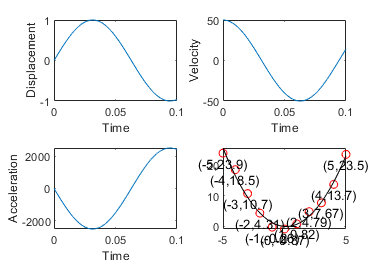

x2 = linspace(-5,5);
y2 = polyval(p, x2);
h = plot(x1, y1, 'or', x2, y2, '-k');
for k = 1:length(x1)
    txt{k} = sprintf('(%g,%g)', x1(k), y1(k)); % 產生欲顯示的圈圈文字串
end
text(x1, y1-0.5, txt, ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top')

# Modifies Example02_12e to include a Legend in the Figure.

x = linspace(0,pi/2,20);
n = 4;
k = (1:n);
[X, K] = meshgrid(x, k);
sinx =cumsum(((-1).^(K-1)).*(X .^ (2*K-1))./factorial(2*K-1)) % cumsum函數通常用於計算一個數組各行的累加值

sinx =          0    0.0827    0.1653    0.2480    0.3307    0.4134    0.4960    0.5787    0.6614    0.7441    0.8267    0.9094    0.9921    1.0748    1.1574    1.2401    1.3228    1.4054    1.4881    1.5708
         0    0.0826    0.1646    0.2455    0.3247    0.4016    0.4757    0.5464    0.6132    0.6754    0.7326    0.7841    0.8293    0.8678    0.8990    0.9223    0.9370    0.9428    0.9389    0.9248
         0    0.0826    0.1646    0.2455    0.3247    0.4017    0.4759    0.5470    0.6142    0.6773    0.7358    0.7892    0.8374    0.8798    0.9163    0.9467    0.9708    0.9885    0.9997    1.0045
         0    0.0826    0.1646    0.2455    0.3247    0.4017    0.4759    0.5469    0.6142    0.6773    0.7357    0.7891    0.8372    0.8795    0.9158    0.9458    0.9694    0.9863    0.9965    0.9998


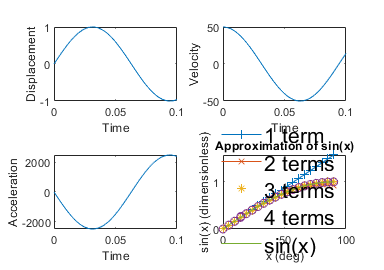

plot(x*180/pi, sinx(1,:), '+-', ...
     x*180/pi, sinx(2,:), 'x-', ...
     x*180/pi, sinx(3,:), '*', ...
     x*180/pi, sinx(4,:), 'o', ...
     x*180/pi, sin(x))
title('Approximation of sin(x)')
xlabel('x (deg)')
ylabel('sin(x) (dimensionless)')
h = legend('1 term', '2 terms', '3 terms', '4 terms', 'Exact');
    h.Position = [0.6, 0.2, 0.25, 0.2];
    h.FontSize = 16;
    h.String{5} = 'sin(x)';
    h.Box = 'off';